First, we define the system variables, equations, and parameters:

beta = 0.98;
sigma = 2;
alpha = 0.36;
delta = 0.025;
z = 1;
rho = 0.95;

syms c k;

u = (c^(1-sigma))/(1-sigma);
f = z*(k^alpha)+(1-delta)*k;

%the derivatives we need
uc = diff(u,c);
ucc = diff(u,c,2);
fz = k^alpha;
fkz = alpha*(k^(alpha-1));
fkk = diff(f,k,2);

%Steady State Values:
eqn = diff(f,k) == 1/beta;
k_s = vpasolve(eqn,k);
c_s = k_s^alpha - delta*k_s;

%Now substitute the ss values into the derivatives:
u_c = subs(uc,c,c_s);
u_cc = subs(ucc,c,c_s);
f_z = subs(fz,k,k_s);
f_kz = subs(fkz,k,k_s);
f_kk = subs(fkk,k,k_s);

%Now define matrix A:
A = [1/beta -1;-u_c*f_kk/u_cc 1+beta*u_c*f_kk/u_cc];

%Now find Eigenvalues and vectors of A:
[V,D] = eig(A);

%Sort by eigenvalue ascending:
[d,ind] = sort(diag(D));
Ds = D(ind,ind);
V = V(:,ind);

We now find V^-1 and C:

V_l = inv(V);

B = [f_z; -beta*u_c*(f_kk*f_z+f_kz*rho)/u_cc];

C = V_l*B;

Now for the values in the equation:

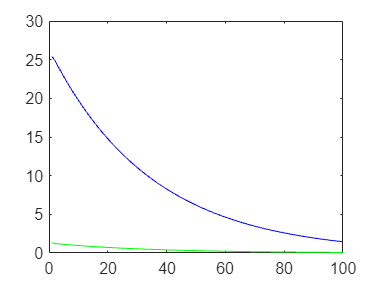

a_1 = -V_l(2,1)/V_l(2,2);
a_2 = -C(2,1)/((Ds(2,2)-rho)*V_l(2,2));

b_1 = 1/beta+V_l(2,1)/V_l(2,2);
b_2 = f_z+C(2,1)/((Ds(2,2)-rho)*V_l(2,2));

syms k_t z_t
C = a_1*k_t+a_2*z_t;
K = b_1*k_t+b_2*z_t;

%Now plot the time path for 100 period:
T=100;
%First, set the shocks and initial reaction in capital as 0:
z = zeros(T,1);
k = zeros(T,1);
c = zeros(T,1);

z(1) = 0.1;
k(1) = k_s;

%Then set the dynamic policy iteration:
for t=1:T-1
    c(t) = subs(C, {k_t z_t}, {k(t) z(t)});
    k(t+1) = subs(K,{k_t z_t},{k(t) z(t)});
end

%Ploting k as blue line, c as green line
g1 = plot([1:T],k,'b', [1:T],c,'g');


impulse_func(2)

在当前文件夹或 MATLAB 路径中未找到 impulse_func，但它存在于:
 D:\GitHub\ECMA31140\Exam\Q1

更改 MATLAB 当前文件夹 或 将其文件夹添加到 MATLAB 路径

test

QQ=[0.5,0.5;0.075,0.925]
QQ(:,1)